# Loop shaping example #1

Consider the following system


$$G(s) = \frac{30}{(s+10)(s+3)}$$


with the control requirements

- $e_\infty = 0$ for a reference signal $r(t)=\mathbf{1}(t)$

- attenuation $\ge95\%$ for a noise signal in the frequency range $\omega \in \left[100,  \infty \left[ $ rad/s

- 
$$s_{\%} \le 20\%$$


- $t_{a,1\%} \le 0.5$s

## Control requirements

First, translate the requirements on the step response into requirements on $L(i\omega)$. The first two requirements yield

- 
$$\mu=1$$


- $|L(i\omega)|_{dB} \le -26$dB in $\omega \in \left[100,  \infty \left[ $ rad/s

For what concerns the maximum overshoot, it is linked to the damping factor of the closed loop system by the formula


$$s = e^{\frac{-\pi \zeta}\sqrt{1-\zeta^2}}$$


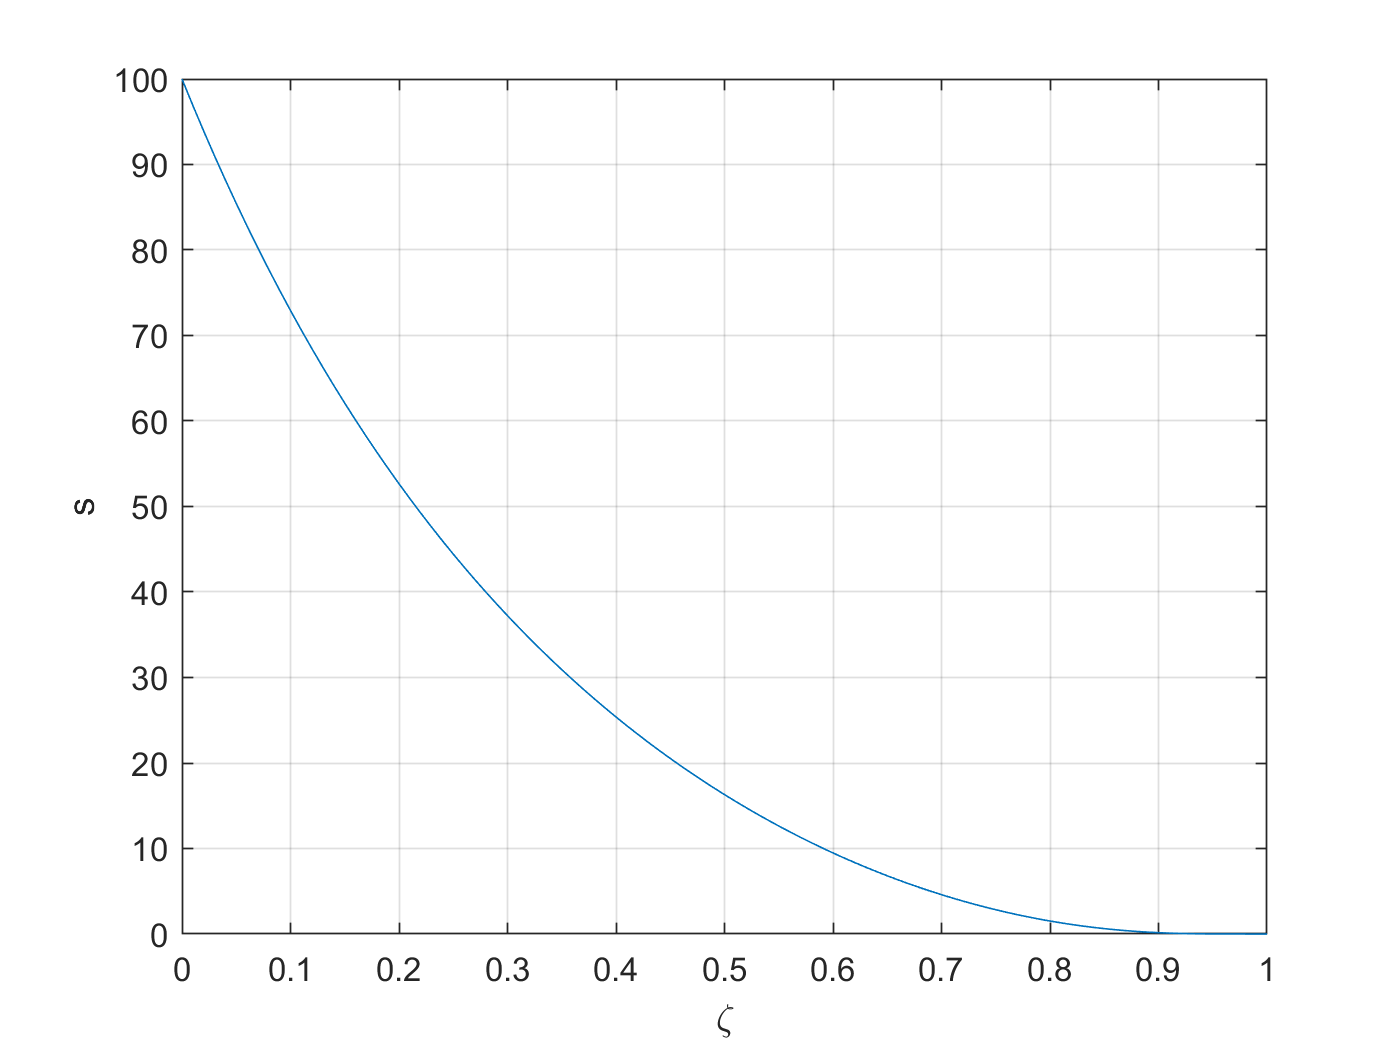

zeta = 0:1e-2:1;
figure
plot(zeta, 100*exp(-pi*zeta./sqrt(1-zeta.^2))), grid on
xlabel('\zeta'),ylabel('s')

So the requirement on the maximum overshoot becomes

         3.  $\zeta \ge 0.45 \rightarrow \varphi_M \ge 100\zeta =45\degree $

This means that we can approximate the closed loop system with a second order transfer function


$$W(s) = \frac{1}{1+\frac{2\zeta s}{\omega_n} + \frac{s^2}{\omega_n^2}}$$


The settling time requirement yields

         4.  $t_{s,1\%} \approx \frac{4.6}{\zeta \omega_n} \approx \frac{4.6}{0.45 \omega_c} \le 0.5$s $\rightarrow \omega_c \ge 20$rad/s

where $\omega_c$ is the crossing frequency of $L(i\omega)$.

## Solution

Define the system's transfer function. 

s = tf('s');
G = 30/(s+10)/(s+3);

Show Bode plot for G(s)

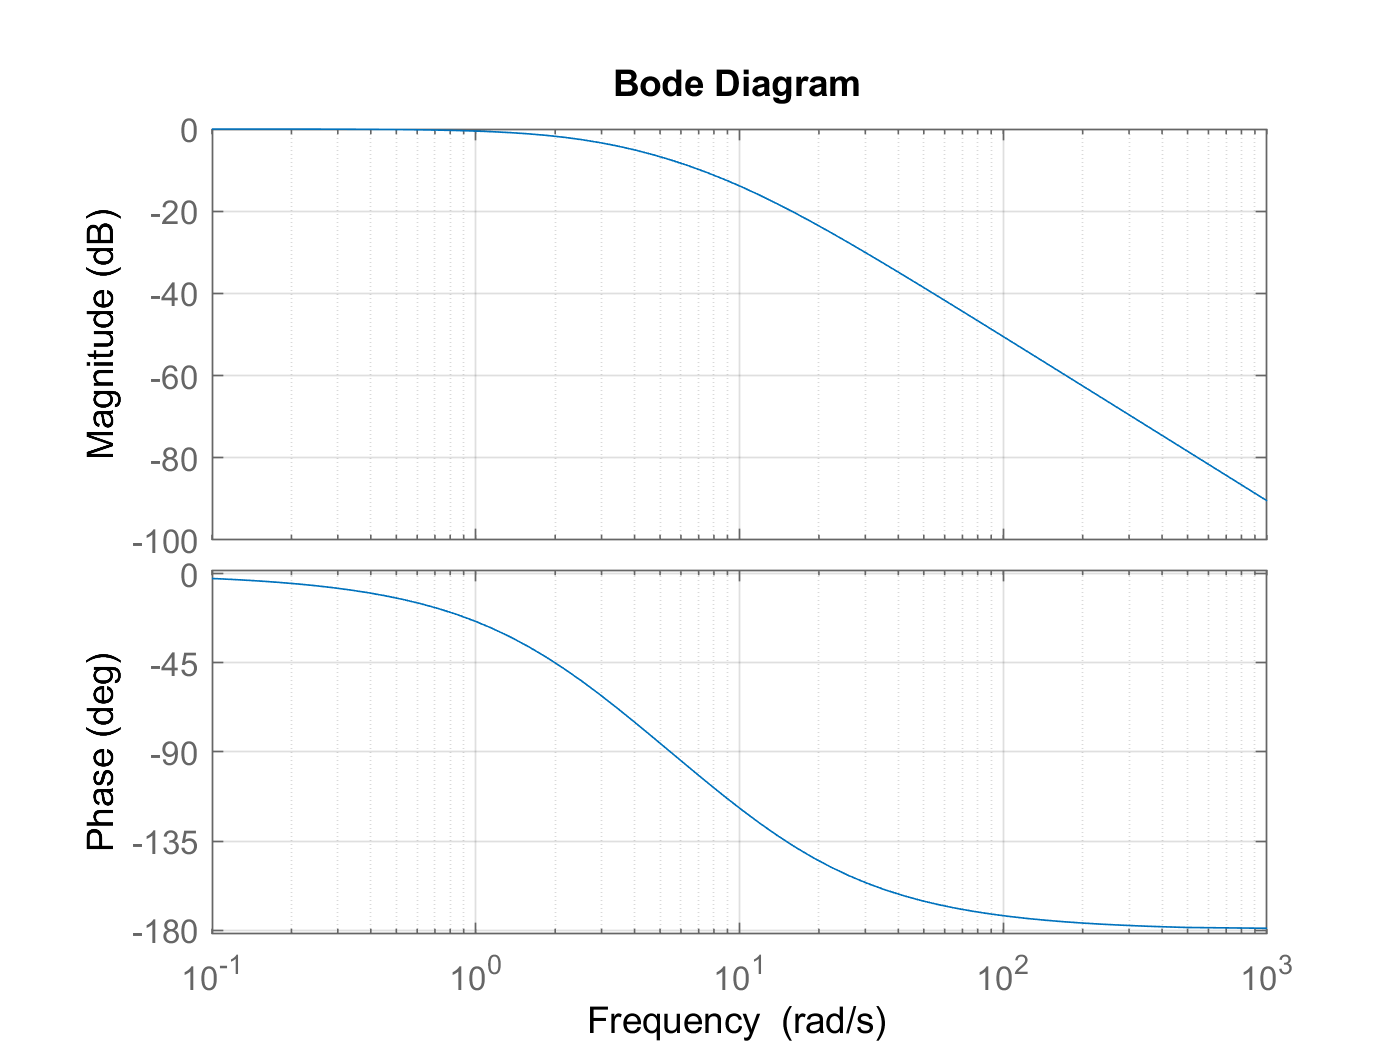

bode(G), grid on

Define K1(s) controller for steady-state requirements (just an integrator for now) and show Bode plot

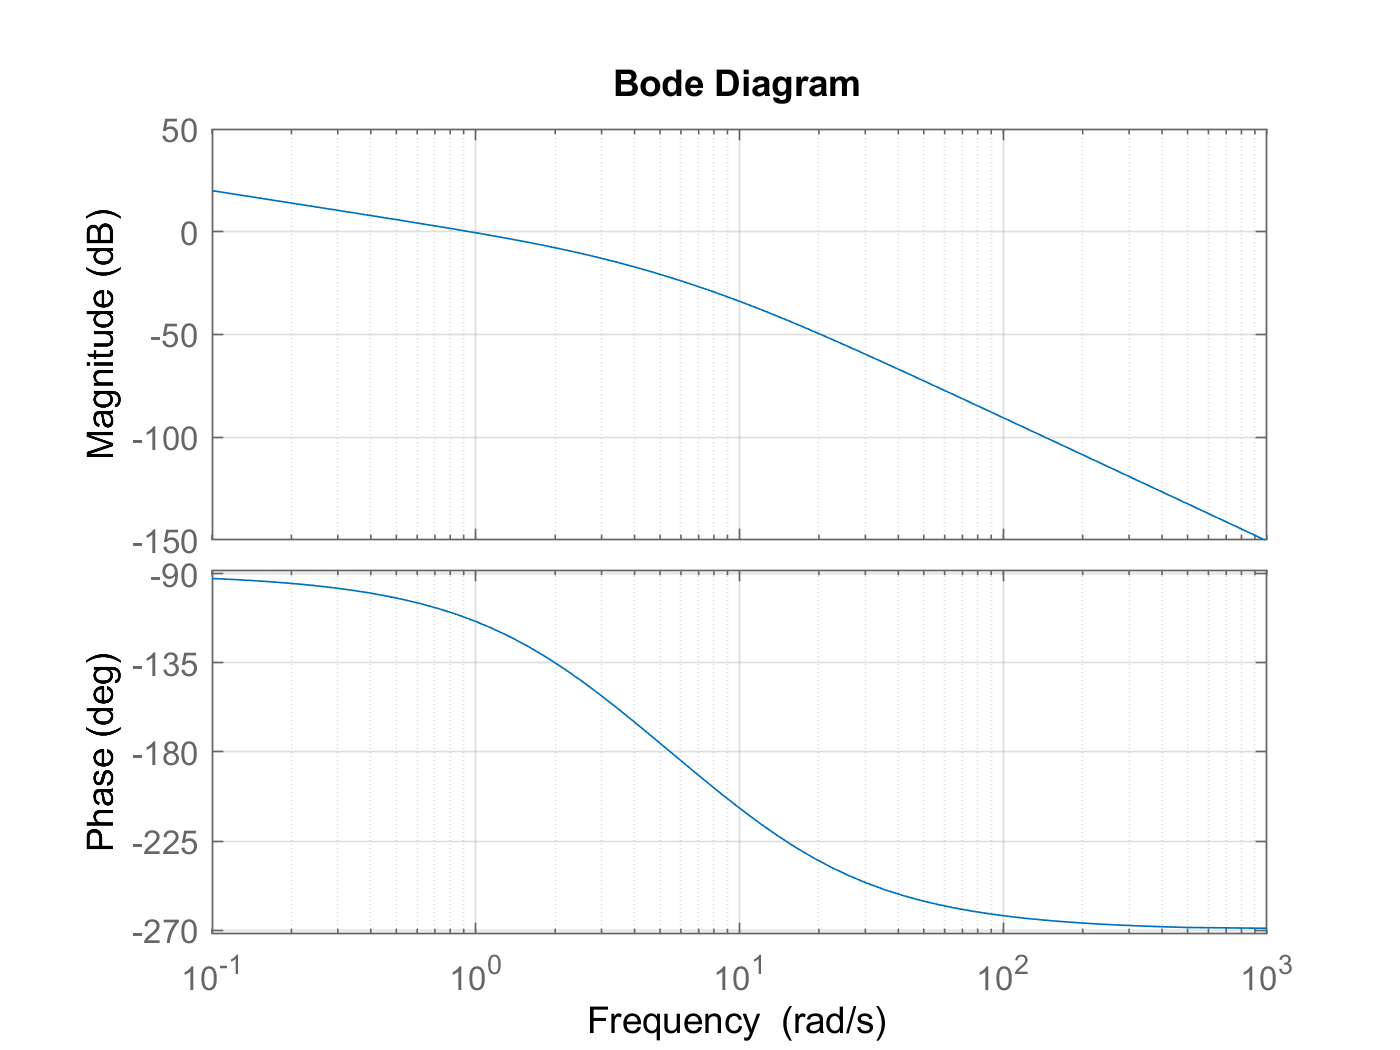

K1 = 1/s;
L1 = K1*G;
bode(L1), grid on

Add a lead network to obtain a 45° lead at the crossing frequency

LN = (1+s/2)/(1+s/20)

LN =
 
  20 s + 40
  ---------
  2 s + 40
 
Continuous-time transfer function.



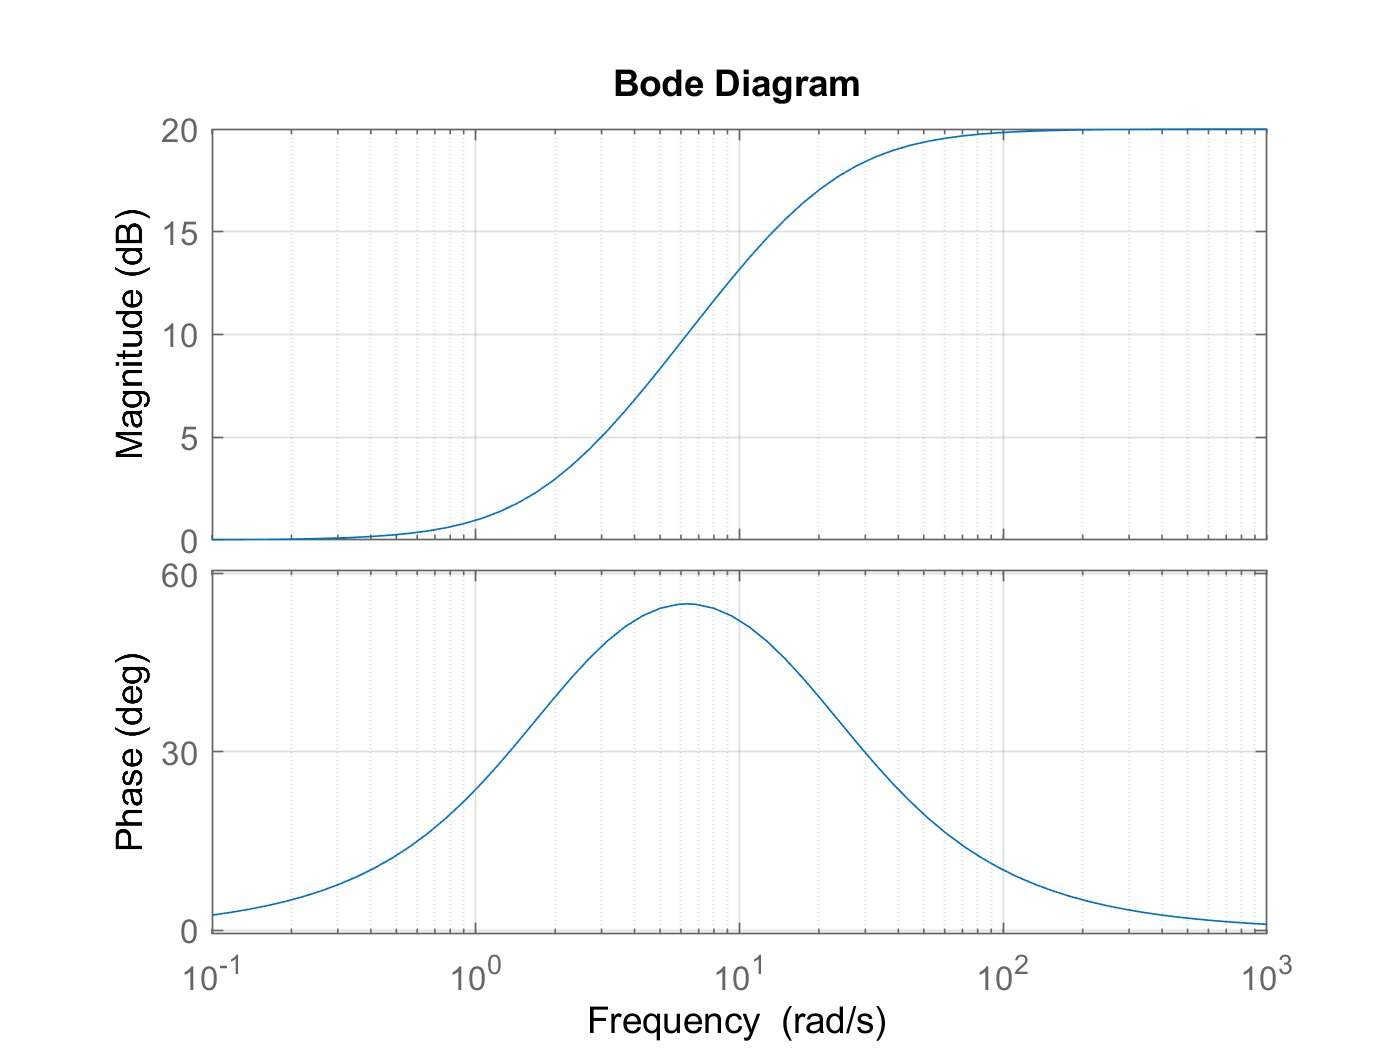

bode(LN), grid on

Add a zero to increase the phase lead up to 100°

Z = 1+s/10;

and adjust gain to obtain the desired crossing frequency

k0 = 20;

Plot results and verify that all the constraints are satisfied

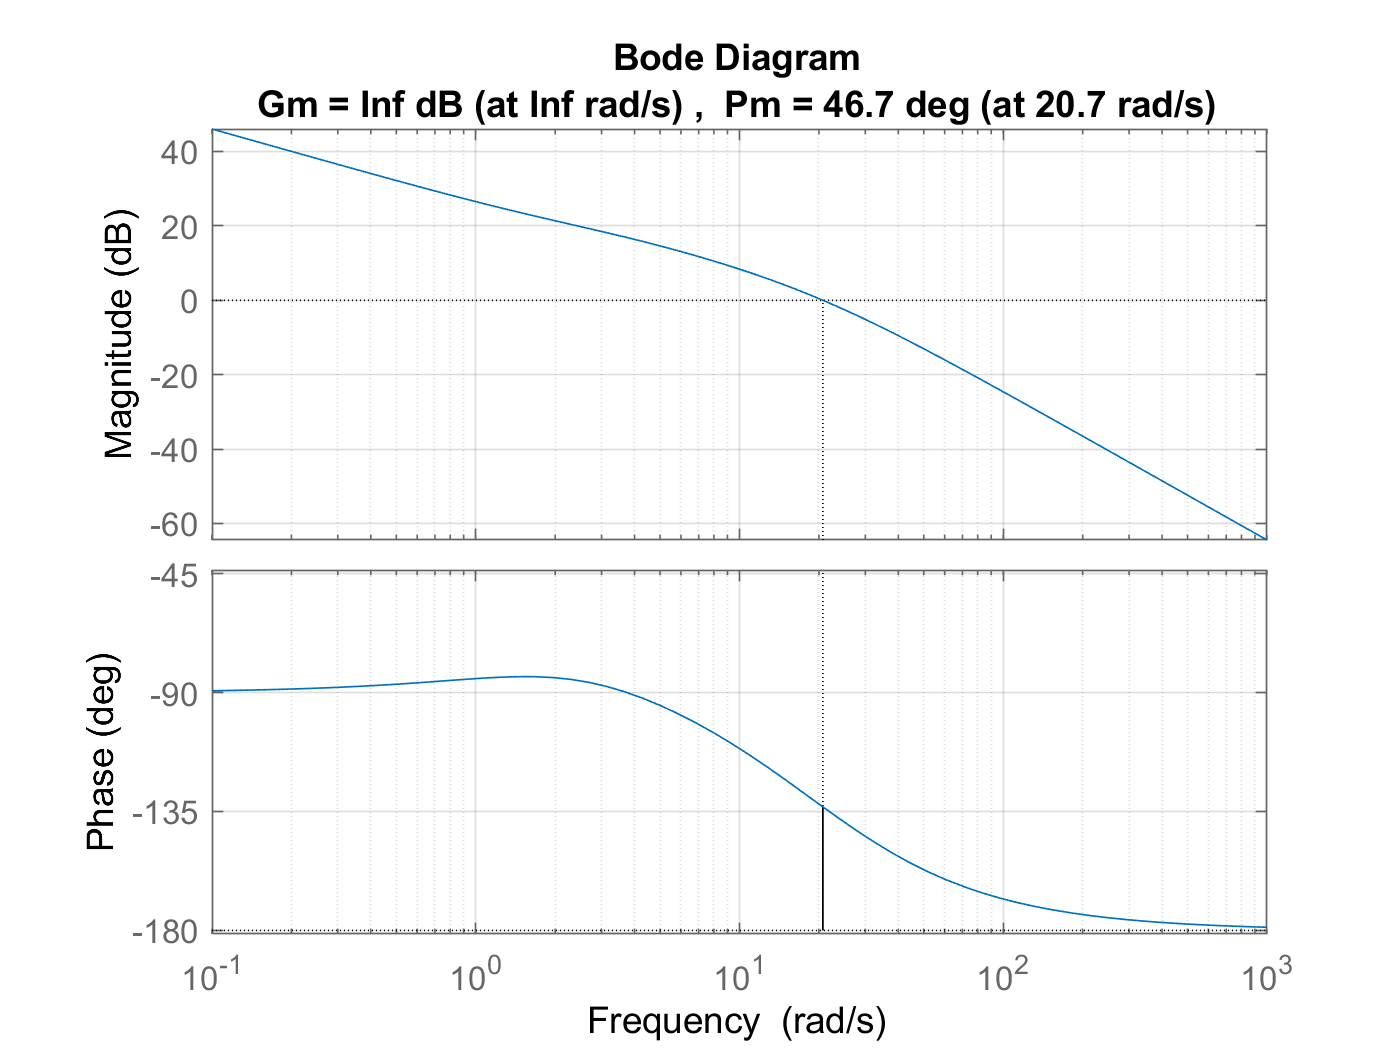

K = k0*K1*LN*Z;
margin(K*G), grid on

Closed loop step response

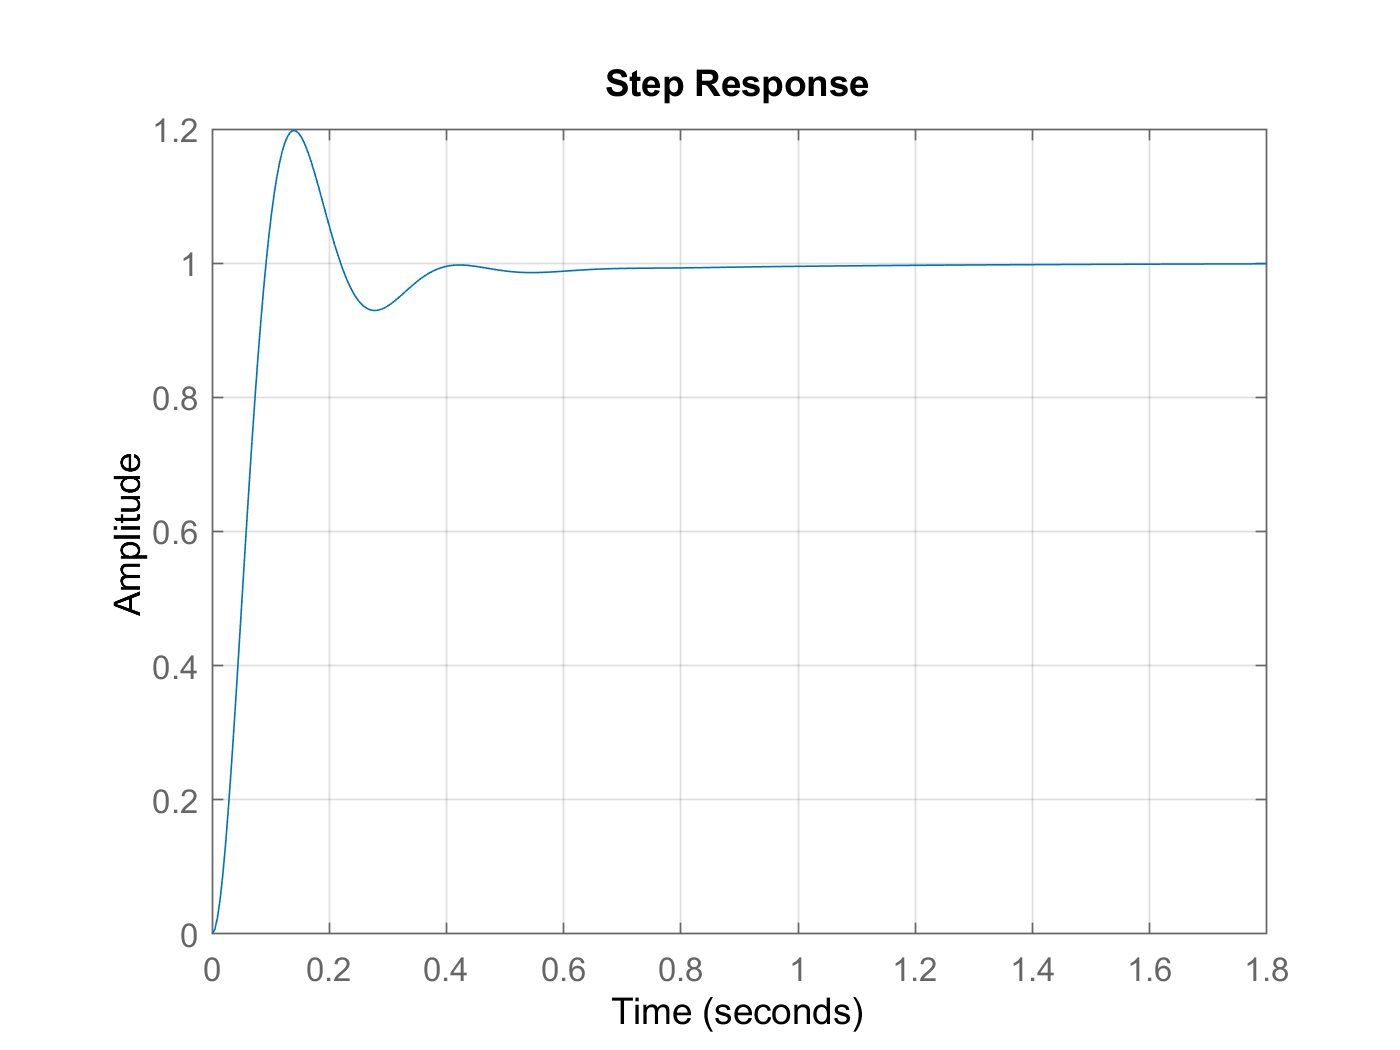

W = (K*G)/(1+K*G);
step(W), grid on